# Analisis de tendencia


ae = exist("arr_ndvi","var");
if ae == 0  %si no existe, cargar la infromación
    new_cargar_informacion
end

## Filtrar información

% Declaraciones
% Los años que se desean consultar
meses = [4,9];
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_tendencia =zeros(length(anios),6);


arr_ndvi_lf(arr_ndvi_lf<=0)=nan; 

bp=waitbar(0,'Filtrando información'); 

for y= 1:length(anios)

        % Abril 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 4  ); % Abril
        if( ~isempty (tmp))
            % promedio
            tabla_tendencia(y,2) = mean(arr_ndvi_lf (:,:,tmp),"all","omitnan");
            % maximo
            tabla_tendencia(y,1) = max(arr_ndvi_lf (:,:,tmp),[],"all","omitnan");
            % minimo
            tabla_tendencia(y,3) = min(arr_ndvi_lf (:,:,tmp),[],"all","omitnan");

             
        end
   
        % Septiembre 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 9  ); 
        if( ~isempty (tmp))
            % promedio
            tabla_tendencia(y,5) = mean(arr_ndvi_lf (:,:,tmp),"all","omitnan");
            % maximo
            tabla_tendencia(y,4) = max(arr_ndvi_lf (:,:,tmp),[],"all","omitnan");
            % minimo
            tabla_tendencia(y,6) = min(arr_ndvi_lf (:,:,tmp),[],"all","omitnan");
             
        end
                 
    waitbar(y/length(anios),bp,sprintf('Filtrando información: Año: (%4d) ',anios(y)));

end
close(bp); 


### 4.- Usar los datos obtenidos 

Regresion lineal en mes de abril

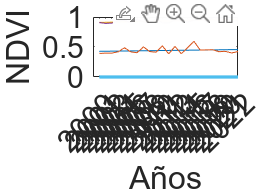


[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,2)');

figure;
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,2));
%title('NDVI promedio x estación');
xlabel('Años','FontSize',18);
xticks(1:length(anios));
xticklabels(anios);
ylabel('NDVI','FontSize',18);
%xlim([0 (length(linea_tiempo_promedio)+1)]);
%ylim([0.2 0.8]);
xtickangle(45);
ax = gca;
ax.FontSize=18; 

hold on
[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,1)');
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,1));

[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,3)');
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,3),LineWidth=2);
hold off

exportgraphics(gca,"img/new_tendencia_promedio_año.png",'Resolution',300) 

## Mes de septiembre

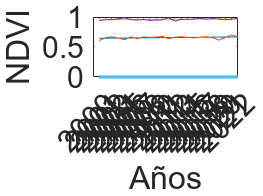


[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,5)');

figure;
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,5));
%title('NDVI promedio x estación');
xlabel('Años','FontSize',18);
xticks(1:length(anios));
xticklabels(anios);
ylabel('NDVI','FontSize',18);
%xlim([0 (length(linea_tiempo_promedio)+1)]);
%ylim([0.2 0.8]);
xtickangle(45);
ax = gca;
ax.FontSize=18; 

hold on
[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,4)');
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,4));

[~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,6)');
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,6),LineWidth=2);
hold off

exportgraphics(gca,"img/new_tendencia_promedio_año.png",'Resolution',300) 